para 

clear all, clc;

Igualación de coeficientes

syms s;
syms k b0 b1 b2 'real';
H(s)=k/( b0 +  b1*s + s^2)

$$H(s) = \frac{k}{s^{2}+b_{1}\,s+b_{0}}$$


M(s)=(H(s)+H(-s))/2

$$M(s) = \frac{0.5000\,k}{s^{2}+b_{1}\,s+b_{0}}+\frac{0.5000\,k}{s^{2}-b_{1}\,s+b_{0}}$$

N(s)=(H(s)-H(-s))/2

$$N(s) = \frac{0.5000\,k}{s^{2}+b_{1}\,s+b_{0}}-\frac{0.5000\,k}{s^{2}-b_{1}\,s+b_{0}}$$


tau(s)=- ( M(s)*diff(N(s),s,1) - diff(M(s),s,1)*N(s) )/ ((M(s))^2 - (N(s))^2);
simplify(tau(s),'Step',10)

$$ans = \frac{b_{1}\,\left(b_{0}-s^{2}\right)}{{b_{0}}^{2}+2\,b_{0}\,s^{2}-{b_{1}}^{2}\,s^{2}+s^{4}}$$

%tau0=b1/b0=3


e(s)=tau(s)-3;
collect(e(s))

$$ans = -\frac{3\,{b_{0}}^{2}-b_{0}\,b_{1}+3\,s^{4}+s^{2}\,\left(-3\,{b_{1}}^{2}+b_{1}+6\,b_{0}\right)}{s^{2}\,\left(2\,b_{0}-{b_{1}}^{2}\right)+{b_{0}}^{2}+s^{4}}$$

% b1/b0=3                  =>   
% 3b0 -  b1 = 0            =>     b1=3*b0 b0=1/3
% -3 b1^2 + b1 + 6b0 =0    =>    -3 b1^2 + b1 + 2b1 =0 
%                          =>    -3 b1 + 3 =0               
%                          =>       b1 = 1

H(s)=subs(H(s), [k b0 b1],[1/3 1/3 1] )

$$H(s) = \frac{0.3333}{s^{2}+s+0.3333}$$

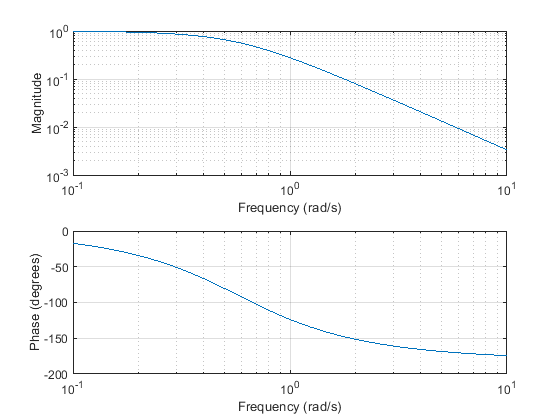


figure
[b,a]=numden(collect(H(s)));
B=sym2poly(b);
A=sym2poly(a);
freqs(B,A)